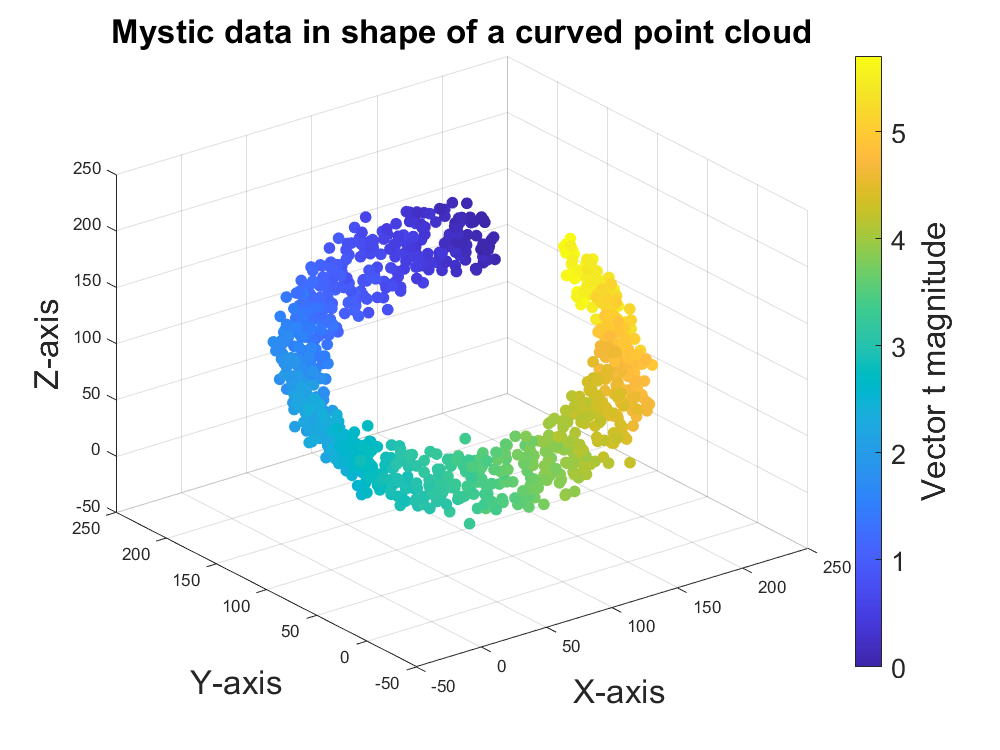

data = readtable('mysticdata.csv','Delimiter',';','VariableNamingRule',"preserve");
disp("The column names are: ")
disp(data.Properties.VariableNames)  

% extract variables
x = data.x;
y = data.y;
z = data.z;
t = data.t;

% create 3D plot
fig = figure('Position', [100 100 800 600]);
ax = axes('Parent', fig, 'Projection', 'orthographic');
scatter = scatter3(ax, x, y, z, 50, t, 'filled');

% add colorbar
color = colorbar(ax, 'Location', 'EastOutside', 'FontSize', 16);
color.Label.String = 'Vector t magnitude';
color.Label.FontSize = 20;

% add grid lines on all axes
grid(ax, 'on');

% set axis labels and title
xlabel(ax, 'X-axis', 'FontSize', 20);
ylabel(ax, 'Y-axis', 'FontSize', 20);
zlabel(ax, 'Z-axis', 'FontSize', 20);
title(ax, 'Mystic data in shape of a curved point cloud', 'FontSize', 20);